# Kapittel 0.1 

## CP1

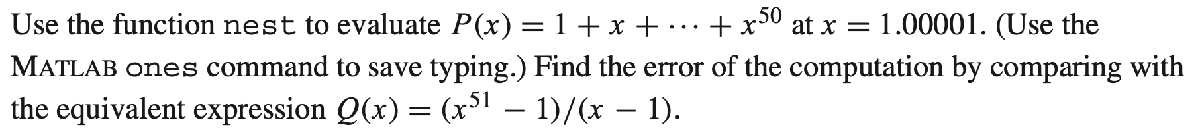

c = ones(1,51);
x = 1.00001;
d = 50;
b = zeros(d,1);

nestValue = nest(d,c,x,b)

nestValue =   51.012752082749991


exactValue = (x^51-1)/(x-1)

exactValue =   51.012752082745230


Finner feilen:

abs(exactValue - nestValue)

ans =      4.760636329592671e-12


# Kapittel 0.2 

## E3

##  

### a)


$$\mathrm{heltallsdel}:{10}_{10} ={1010}_2$$



$$\mathrm{desimaldel}:0\ldotp 5=0\ldotp 1_2$$



$$10\ldotp 5_{10} =1010\ldotp 1_2$$


### b)

$\frac{1}{3}$ til binær kan gjøres slik:

 $\begin{array}{l}
2*\frac{1}{3}=\frac{2}{3}+0\\
2*\frac{2}{3}=\frac{1}{3}+1
\end{array}$ Vi ser at $\frac{1}{3}$ går igjen og vil repetere seg.

Vi får da at:


$${\frac{1}{3}}_{10} ={0\ldotp \bar{01} }_2 \;$$


### c)


$$\begin{array}{l}
2*\frac{5}{7}=\frac{3}{7}+1\\
2*\frac{3}{7}=\frac{6}{7}+0\\
2*\frac{6}{7}=\frac{5}{7}+1
\end{array}$$


$\frac{5}{7}$dukker opp på nytt og vi får $\frac{5}{7}=101101101\ldotp \ldotp \ldotp_2 ={0\ldotp \bar{101} }_2 \;$

### d)


$$12=8+4=2^3 +2^2 =1100$$



$$\begin{array}{l}
2*0\ldotp 8=0\ldotp 6+1\\
2*0\ldotp 6=0\ldotp 2+1\\
2*0\ldotp 2=0\ldotp 4+0\\
2*0\ldotp 4=0\ldotp 8+0
\end{array}$$


vi får $0\ldotp 8$på nytt altså får vi repeterende sekvens


$$12\ldotp 8_{10} =1100\ldotp \overline{{1100}_2 }$$


### e)

heltallsdelen:


$$\begin{array}{l}
\frac{55}{2}=27+1\\
\frac{27}{2}=13+1\\
\frac{13}{2}=6+1\\
\frac{6}{2}=3+0\\
\frac{3}{2}=1+1\\
\frac{1}{2}=0+1
\end{array}$$



$${55}_{10} ={110111}_2$$


desimaldelen:


$$\begin{array}{l}
2*0\ldotp 4=0\ldotp 8+0\\
2*0\ldotp 8=0\ldotp 6+1\\
2*0\ldotp 6=0\ldotp 2+1\\
2*0\ldotp 2=0\ldotp 4+0
\end{array}$$


Da får vi:


$$55\ldotp 4_{10} =110111\ldotp {\overline{0110} }_2$$


## E7 

### f)

skal konvertere $110\ldotp {1\bar{101} }_2$ til desimaltall.

begynner med heltallsdelen: ${110}_2 =\left(1*2^2 \right)+\left(1*2^1 \right)+\left(0*2^0 \right)=2^2 +2^1 =4+2=6_{10}$

deretter decimaldelen:

 
$$\begin{array}{l}
\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;x=0\ldotp 1\bar{101} \\
\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;8x=110\ldotp 1\bar{101} \\
\;\;\;\;\;\;\;\;8x-x=110\ldotp 1\bar{101} -0\ldotp 1\bar{101} \\
\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;7x={110}_2 =6\\
\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;x=\frac{6}{7}
\end{array}$$


Altså får vi:  $6\frac{6}{7}=\frac{42}{7}+\frac{6}{7}=\frac{48}{7}$

# Kapittel 0.3 

## E5 

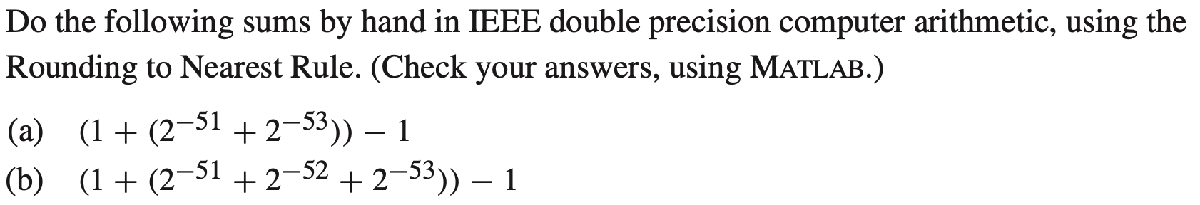

### a)

%   0.0000000000000000000000000000000000000000000000000010   x 2^0       2^-51
% + 0.0000000000000000000000000000000000000000000000000000.1 x 2^0     + 2^-53
% = 0.0000000000000000000000000000000000000000000000000010   x 2^0
% + 1.0000000000000000000000000000000000000000000000000000   x 2^0     + 1
% = 1.0000000000000000000000000000000000000000000000000010   x 2^0
% - 1.0000000000000000000000000000000000000000000000000000   x 2^0     - 1
% = 0.0000000000000000000000000000000000000000000000000010   x 2^0 = 2^-51 
% = 2*2^-52 = 2 * emach

a = (1+(2^-51+2^-53))-1

a =      4.440892098500626e-16


a_manual_answer = 2^-51

a_manual_answer =      4.440892098500626e-16


a_emach = 2*2^-52 %2 emach

a_emach =      4.440892098500626e-16


### b)

%   0.0000000000000000000000000000000000000000000000000010   x 2^0        2^-51
% + 0.0000000000000000000000000000000000000000000000000001   x 2^0      + 2^-52
% = 0.0000000000000000000000000000000000000000000000000011   x 2^0
% + 0.0000000000000000000000000000000000000000000000000000.1 x 2^0      + 2^-53
% = 0.0000000000000000000000000000000000000000000000000100   x 2^0
% + 1.0000000000000000000000000000000000000000000000000000   x 2^0      + 1
% = 1.0000000000000000000000000000000000000000000000000100   x 2^0
% - 1.0000000000000000000000000000000000000000000000000000   x 2^0      - 1
% = 0.0000000000000000000000000000000000000000000000000100   x 2^0 = 2^-50 
% = 2*2^-51 = 4*2^-52 = 4 * emach

b = (1+(2^-51+2^-52+2^-53))-1  

b =      8.881784197001252e-16


b_manual_answer = 2^-50

b_manual_answer =      8.881784197001252e-16


b_emach = 4*2^-52 %4 * emach

b_emach =      8.881784197001252e-16


# Kapittel 0.4 

## E1 

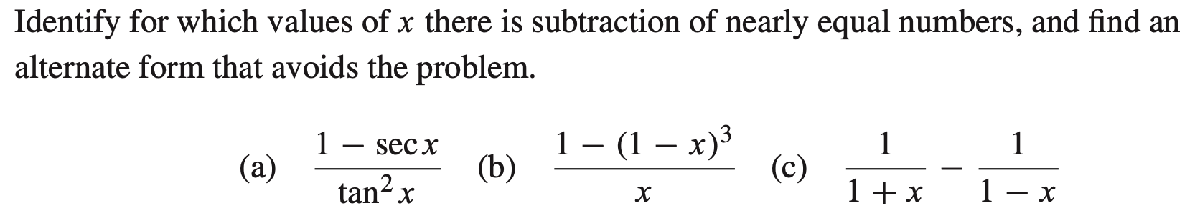

### a)


$$\begin{array}{l}
\frac{1-\sec \left(x\right)}{\tan^2 x}=\\
\frac{\left(1-\sec \left(x\right)\right)*\left(1+\sec \left(x\right)\right)}{\tan^2 x*\left(1+\sec \left(x\right)\right)}=\\
\frac{1+\sec \left(x\right)-\sec \left(x\right)-\sec^2 \left(x\right)}{\tan^2 x*\left(1+\sec \left(x\right)\right)}=\\
\frac{-1\left(\sec^2 x-1\right)}{\tan^2 x*\left(1+\sec \left(x\right)\right)}=\\
\frac{-\left(\tan^2 x\right)}{\tan^2 x*\left(1+\sec \left(x\right)\right)}=\\
\frac{-1}{1+\sec \left(x\right)}
\end{array}$$


## CP1 

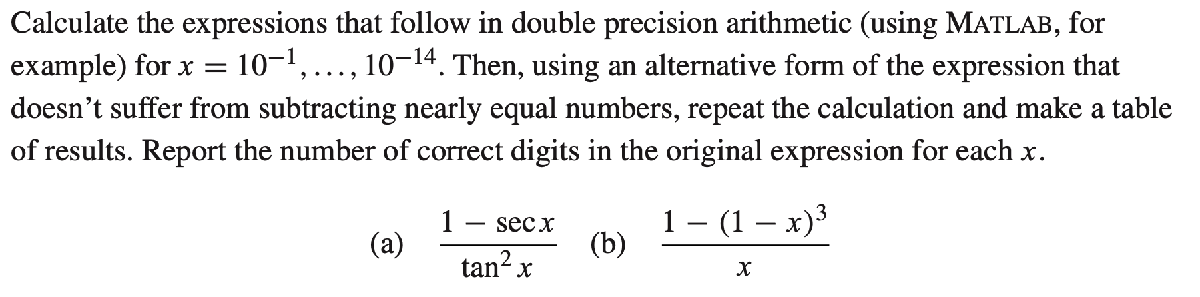

### a)

eksp = -1:-1:-14;
x = 10.^eksp;

res = ones(14:3);
res(1:14,1) = x;
res(1:14,2) = (1-sec(x))./(tan(x).^2); %vanlig uttrykk
res(1:14,3) = (-1)./(1+sec(x)); %omskrevet uttrykk

%T.Properties.VariableNames = {'x' 'vanlig' 'omskrevet'};
T = table(res(1:14,1),res(1:14,2),res(1:14,3))

T = 14×3 table
     Var1            Var2                  Var3       
    ______    __________________    __________________

       0.1    -0.498747913711435    -0.498747913711429
      0.01    -0.499987499790956    -0.499987499791664
     0.001    -0.499999875014289    -0.499999874999979
    0.0001    -0.499999993627931        -0.49999999875
     1e-05    -0.500000041336852      -0.4999999999875
     1e-06    -0.500044450290837    -0.499999999999875
     1e-07    -0.510702591327569    -0.499999999999999
     1e-08                     0                  -0.5
     1e-09                     0                  -0.5
     1e-10                     0                  -0.5
     1e-11                     0                  -0.5
     1e-12                     0                  -0.5
     1e-13                     0                  -0.5
     1e-14                     0                  -0.5


## CP5

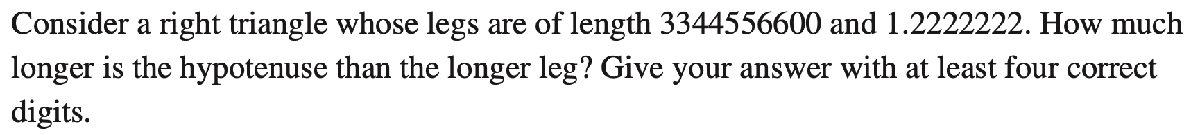

prøver først å beregne hypothenusen på vanlig måte:

leg1 = 3344556600;
leg2 = 1.2222222;
hyp = sqrt(leg1^2+leg2^2)

hyp =      3.344556600000000e+09


og vi ser at hypotenusen og leg1 blir like lange:

diff = hyp - leg1

diff =      0


vi kan så skrive om denne differeansen for å unngå feil.


$$\frac{\textrm{hyp}-\textrm{leg1}}{1}=\frac{\left(\textrm{hyp}-\textrm{leg1}\right)*\left(\textrm{hyp}+\textrm{leg1}\right)}{1*\left(\textrm{hyp}+\textrm{leg1}\right)}=\frac{{\textrm{hyp}}^2 -{\textrm{leg1}}^2 }{\textrm{hyp}+\textrm{leg1}}=\frac{{\textrm{leg2}}^2 }{\textrm{hyp}+\textrm{leg1}}$$


den korrekte differansen mellom leg1 og hypotenusen blir altså:

leg2^2 / (hyp+leg1)

ans =      2.233221447310594e-10


# Kapittel 0.5 

## E8 

### a) 


$$f\left(x\right)=\cos \left(x\right)$$


for å finne 5te grad Taylor-polynomet til $f\left(x\right)$ trenger å finne de første 5 deriverte av $f\left(x\right)$:

vi får:


$$\begin{array}{l}
f´\left(x\right)\;\;=-\sin \left(x\right)\\
f^2 \left(x\right)\;\;=-\cos \left(x\right)\\
f^3 \left(x\right)\;\;=\;\;\;\sin \left(x\right)\\
f^4 \left(x\right)\;\;=\;\;\;\cos \left(x\right)\\
f^5 \left(x\right)\;\;=-\sin \left(x\right)
\end{array}$$


5-grads Taylor-polynomet:


$$P_5 \left(x\right)=f\left(x_0 \right)+f´\left(x_0 \right)\left(x-x_0 \right)+\frac{f^2 \left(x_0 \right){\left(x-x_0 \right)}^2 }{2!}+\frac{f^3 \left(x_0 \right){\left(x-x_0 \right)}^3 }{3!}+\frac{f^4 \left(x_0 \right){\left(x-x_0 \right)}^4 }{4!}+\frac{f^5 \left(x_0 \right){\left(x-x_0 \right)}^5 }{5!}$$


blir altså:


$$P_5 \left(x\right)=\cos \left(x_0 \right)-\sin \left(x_0 \right)\left(x-x_0 \right)-\frac{\cos \left(x_0 \right){\left(x-x_0 \right)}^2 }{2}+\frac{\sin \left(x_0 \right){\left(x-x_0 \right)}^3 }{6}+\frac{\cos \left(x_0 \right){\left(x-x_0 \right)}^4 }{24}-\frac{\sin \left(x_0 \right){\left(x-x_0 \right)}^5 }{120}$$


sentrert rundt $x=0$ får vi $x_0 =0$:


$$P_5 \left(x\right)=\cos \left(0\right)-\sin \left(0\right)\left(x-0\right)-\frac{\cos \left(0\right){\left(x-0\right)}^2 }{2}+\frac{\sin \left(0\right){\left(x-0\right)}^3 }{6}+\frac{\cos \left(0\right){\left(x-0\right)}^4 }{24}-\frac{\sin \left(0\right){\left(x-0\right)}^5 }{120}$$



$$P_5 \left(x\right)=1-0\left(x\right)-\frac{1{\left(x\right)}^2 }{2}+\frac{0{\left(x\right)}^3 }{6}+\frac{1{\left(x\right)}^4 }{24}-\frac{0{\left(x\right)}^5 }{120}$$



$$P_5 \left(x\right)=1-\frac{x^2 }{2}+\frac{x^4 }{24}$$


### b)

finner først restleddet til $P_5 \left(x\right)$:


$$R_6 \left(x\right)=\frac{f^{\left(6\right)} \left(c\right)*{\left(x-x_0 \right)}^6 }{6!}=\frac{-\cos \left(c\right)*x^6 }{6!}$$


vi ser at den største verdien vi kan få av $R_6 \left(x\right)=\frac{x^6 }{6!}$ siden $\left|-\cos \left(c\right)\right|\le 1$

x kan være i intervallet $\left\lbrack -\frac{\pi }{4},\frac{\pi }{4}\right\rbrack$ altså er $\left|x\right|\le \frac{\pi }{4}$ 

den største feilen vi kan få ved å bruke $P_5 \left(x\right)$ blir altså: $\frac{{\left(\frac{\pi }{4}\right)}^6 }{6!}$ 

error = (pi/4)^6/factorial(6)

error =      3.259918869273900e-04


# Kapittel 1.1 

## E1

Intermediate Value Theorem / Skjæringssetningen sier at dersom f(x) er kontinuerlig i ett intevall fra a til b, vil funksjonen på et punkt være alle verdier mellom f(a) og f(b).

$x^3 =9\;$gir oss at $f\left(x\right)=0$ når $x^3 -9=0$

setter opp en tabell:

x = (1:5);
fx = x.^3-9;

res = zeros(5:2);
res(1,1:5) = x;
res(2,1:5) = fx

res =      1     2     3     4     5
    -8    -1    18    55   116


Vi ser at $f\left(x\right)=0$ i minst et punkt i intervallet $\left\lbrack 2,3\right\rbrack$ 

## E3

Fra oppgave 1.1 E1 vet vi at roten vil ligge i intervallet $\left\lbrack 2,3\right\rbrack$, Starter derfor med disse verdiene når vi skal bruke Halveringsmetoden 2 ganger:

x = [2, 2.5, 3];
fx = x.^3-9

fx =   -1.000000000000000   6.625000000000000  18.000000000000000


ser at nullpunktet ligger mellom 2 og 2,5 etter første iterasjon, bruker halveringsmetoden på nytt:

x = [2, 2.25, 2.5];
fx = x.^3-9

fx =   -1.000000000000000   2.390625000000000   6.625000000000000


ser at nullpunktet ligger mellom 2 og 2,25 etter andre iterasjon. 

Dette betyr at roten ligger et sted imellom disse, og vi kan si med 1/8 feilmargin at roten er: $2,125$

# Kapittel 1.2 

## CP1

ønsker å bruke fikspunkt til å finne svar med 8 korrekte desimaler;

korrekte_des = 8;

velger å starte i $x=0$ for alle deloppgavene.

x = 0;

### a) $x^3 =2x+2$

Skriver om:


$$\begin{array}{l}
x^3 =2x+2\\
x\;=\sqrt[3]{2x+2}
\end{array}$$


dette gir:

f = @(x)(2*x+2)^(1/3);

a = fixed_point(f, x, korrekte_des)

x1 = 1.259921050
x2 = 1.653386628
x3 = 1.744255806
x4 = 1.763944280
x5 = 1.768152664
x6 = 1.769049606
x7 = 1.769240656
x8 = 1.769281344
x9 = 1.769290009
x10 = 1.769291855
x11 = 1.769292248
x12 = 1.769292332
x13 = 1.769292349
x14 = 1.769292353


a =    1.769292353211447


### b) $e^x +x=7$

Skriver om:


$$\begin{array}{l}
e^x +x=7\\
{\;\;\;\;\;\;\;\;e}^x =7-x\\
\ln \left(e^x \right)=\ln \left(7-x\right)\\
\;\;\;\;\;\;\;\;\;x=\ln \left(7-x\right)
\end{array}$$


dette gir:

f = @(x)log(7-x);

b = fixed_point(f, x, korrekte_des)

x1 = 1.945910149
x2 = 1.620197787
x3 = 1.682651610
x4 = 1.670974756
x5 = 1.673168340
x6 = 1.672756626
x7 = 1.672833914
x8 = 1.672819406
x9 = 1.672822129
x10 = 1.672821618
x11 = 1.672821714
x12 = 1.672821696
x13 = 1.672821699


b =    1.672821699163366


### c) $e^x +\sin \left(x\right)=4$

Vi skriver om:


$$\begin{array}{l}
e^x +\sin \left(x\right)=4\\
{\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;e}^x =4-\sin \left(x\right)\\
\;\;\;\;\;\;\;\;\;\;\ln \left(e^x \right)=\ln \left(4-\sin \left(x\right)\right)\\
\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;x=\ln \left(4-\sin \left(x\right)\right)
\end{array}$$


dette gir:

f = @(x)log(4-sin(x));

c = fixed_point(f, x, korrekte_des)

x1 = 1.386294361
x2 = 1.104253765
x3 = 1.133616180
x4 = 1.129481187
x5 = 1.130049355
x6 = 1.129971009
x7 = 1.129981807
x8 = 1.129980318
x9 = 1.129980524
x10 = 1.129980495
x11 = 1.129980499


c =    1.129980499122948


# Kapittel 1.3 

## E1

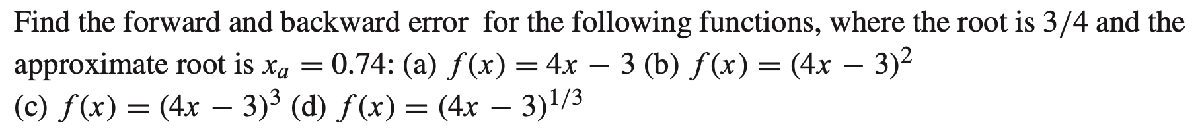

**foroverfeil**: Hvor stor er feilen i forhold til korrekt x

**bakoverfeil:** Hvor stor er feilen i forhold til korrekt y (f(x))

faktisk_nullpunkt = 3/4;
tilnermet_nullpunkt = 0.74;

siden alle funksjonene har de samme faktiske og tilnærmede punktene vil foroverfeilen være den samme:

foroverfeil = faktisk_nullpunkt - tilnermet_nullpunkt

foroverfeil =    0.010000000000000


### a) $f\left(x\right)=4x-3$

f=@(x)(4*x-3);
bakoverfeil = abs(f(tilnermet_nullpunkt))

bakoverfeil =    0.040000000000000


### b) $f\left(x\right)={\left(4x-3\right)}^2$

f=@(x)(4*x-3)^2;
bakoverfeil = abs(f(tilnermet_nullpunkt))

bakoverfeil =    0.001600000000000


### c) $f\left(x\right)={\left(4x-3\right)}^3$

f=@(x)(4*x-3)^3;
bakoverfeil = abs(f(tilnermet_nullpunkt))

bakoverfeil =      6.400000000000017e-05


### d) $f\left(x\right)=\sqrt[3]{4x-3}$

f=@(x)(4*x-3)^(1/3);
bakoverfeil = abs(f(tilnermet_nullpunkt))

bakoverfeil =    0.341995189335340


## E3

### a) $f\left(x\right)=1-\cos \left(x\right)$

f = @(x)1-cos(x);

Multiplisiteten til roten $r=0$ er 2 fordi:


$$\begin{array}{l}
f\left(0\right)\;\;=1-\cos \left(0\right)=0\\
f^{\prime } \left(0\right)\;=\sin \left(0\right)\;\;\;\;\;\;\;\;\;=0\\
f^2 \left(0\right)\;=\cos \left(0\right)\;\;\;\;\;\;\;\;=1\not= 0
\end{array}$$


### b) 

x_a = 0.0001;

foroverfeil = abs(0 - x_a)

foroverfeil =      1.000000000000000e-04


bakoverfeil = abs(f(x_a))

bakoverfeil =      4.999999969612645e-09


# Kapittel 1.4 

## E3

## 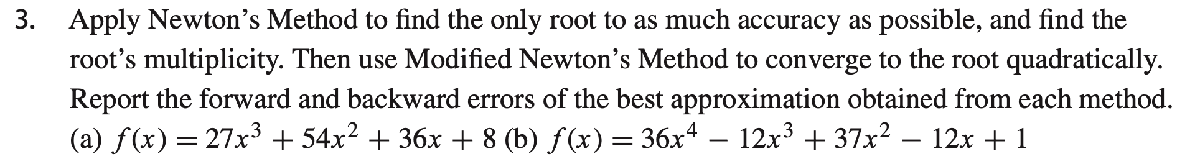

### a) $x^5 -2x^4 +2x^2 -x=0$

finner først de deriverte til funksjonen:


$$f^{\prime } \left(x\right)\;\;=5x^4 -8x^3 +4x-1$$
 

fd = @(x)5*x.^4-8*x.^3+4*x-1;


$$f^2 \left(x\right)\;=20x^3 -24x^2 +4$$


fd2 = @(x)20*x.^3-24*x.^2+4;


$$f^3 \left(x\right)\;=60x^2 -48x$$


fd3 = @(x)60*x.^2-48*x;

røttene vi skal sjekke for er: $r=-1\;,r=0\;,r=1$ altså $r=\left\lbrack -1,\;0,\;1\right\rbrack$

r = (-1:1);

res = zeros(3:4);
res(1:3,1) = r;
res(1:3,2) = fd(r);
res(1:3,3) = fd2(r);
res(1:3,4) = fd3(r)

res =     -1     8   -40   108
     0    -1     4     0
     1     0     0    12


## CP6

## 

Volumet av en kjegle:


$$V_{\textrm{kjeks}} =h\frac{\pi r^2 }{3}$$


Volumet av en halvsirkel:


$$V_{\textrm{kule}} =\frac{2\pi r^3 }{3}$$


Volumet av hele iskremen er da gitt ved:


$$V=h\frac{\pi r^2 }{3}+$$

$$\frac{2\pi r^3 }{3}$$


vi får oppgitt at høyden på iskremen er $10\textrm{cm}$ og at Volumet er $60{\textrm{cm}}^3$dette gir oss:


$$60{\textrm{cm}}^3 =10\textrm{cm}*\frac{\pi r^2 }{3}+\frac{2\pi r^3 }{3}$$



$$f\left(r\right)=10\textrm{cm}*\frac{\pi r^2 }{3}+\frac{2\pi r^3 }{3}-60{\textrm{cm}}^3$$


f = @(r)((10*pi*r.^2)/3)+((2*pi*r.^3)/3)-60;

finner den deriverte:


$$f^{\prime } \left(r\right)=2*10\textrm{cm}*\frac{\pi r}{3}+\frac{6\pi r^2 }{3}$$


fd = @(r)((20*pi*r)/3)+((6*pi*r.^2)/3);

Velger en tilfeldig startverdi og anngir antall riktige desimaler vi ønsker:

Newtons metode: $x_{n+1} =x_n -\frac{f\left(x_n \right)}{f^{\prime } \left(x_n \right)}$

startverdi = 27;
ant_riktige_desimaler = 4;
r = newton(f, fd, startverdi, ant_riktige_desimaler)

x0 = 27.000000000
x1 = 17.517154208
x2 = 11.237508186
x3 = 7.121529455
x4 = 4.497515641
x5 = 2.950407490
x6 = 2.221163856
x7 = 2.032626236
x8 = 2.020160417
x9 = 2.020107322


r =    2.020107321219701


**Vi får ut at r er tilnærmet lik 2,0201 cm**